**Load Data**

clear
close all;
% DATA_Household = xlsread("DATA_Household_File.csv");
load('DATA_Household.mat')


**Question 2-a**

TOTAL: Total trips completed by the household on their assigned survey date,

HHSIZE : Number of people living in the household

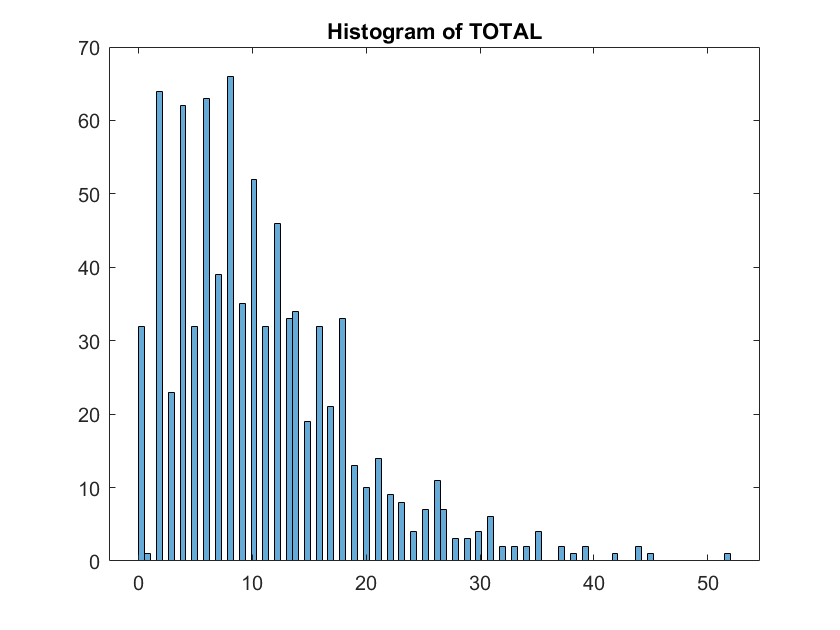

TOTAL = DATA_Household(:,7);
% Take a look at the distribution of TOTAL
figure(1)
histogram(TOTAL,100)
title('Histogram of TOTAL')

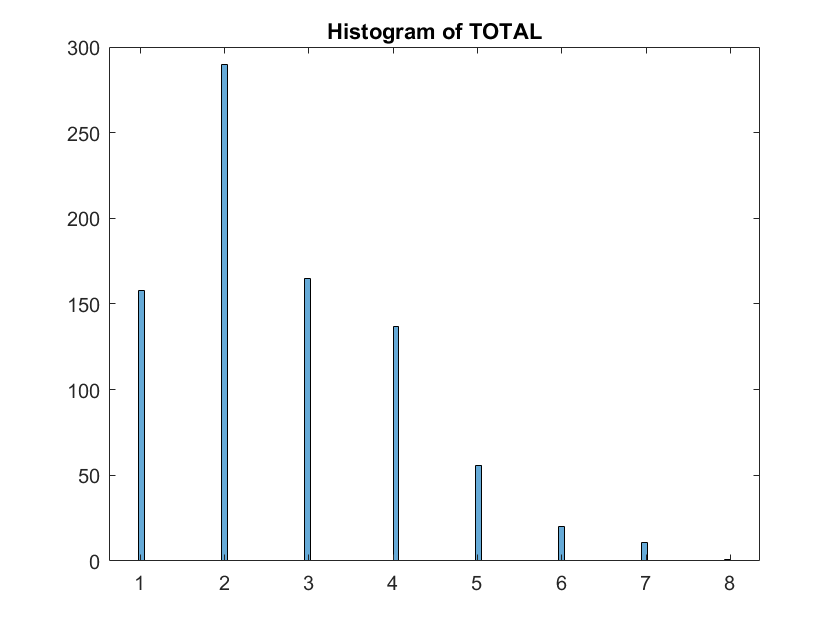


HHSIZE = DATA_Household(:,8);
% Take a look at the distribution of HHSIZE
figure(2)
histogram(HHSIZE,100)
title('Histogram of TOTAL')


TOTAL_Sort = sort(TOTAL,1,"ascend");
Diff_Total = diff(TOTAL_Sort);
Repetition_Num_TOTAL = find(Diff_Total==0)+1;
TOTAL_Sort(Repetition_Num_TOTAL,:) = [];

HHSIZE_Sort = sort(HHSIZE,1,"ascend");
Diff_HHSIZE = diff(HHSIZE_Sort);
Repetition_Num_HHSIZE = find(Diff_HHSIZE==0)+1;
HHSIZE_Sort(Repetition_Num_HHSIZE,:) = [];

H_T = [HHSIZE,TOTAL];
% See Function "PMF"
% PMF_T_H =PMF(HHSIZE_Value,TOTAL_Value,TOTAL,HHSIZE)

figure(3)
h = histogram2(HHSIZE,TOTAL,52,'Normalization','probability')

h =   Histogram2 with properties:

             Data: [838×2 double]
           Values: [52×52 double]
          NumBins: [52 52]
        XBinEdges: [1×53 double]
        YBinEdges: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52]
         BinWidth: [0.1350 1]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


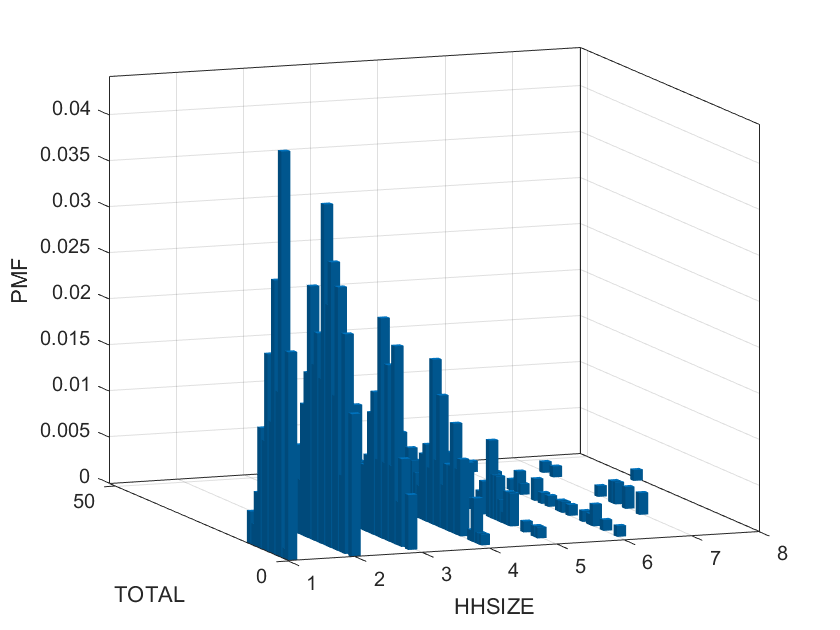

PMF_HHSIZE_TOTAL = h.Values;
xlabel('HHSIZE')
ylabel('TOTAL')
zlabel('PMF')
view([-20.8 11.6])

**Q2b**

Compute

(i) P(HHSIZE = 3, TOTAL = 4)

PMF_H3_T4 =PMF(3,4,TOTAL,HHSIZE)

PMF_H3_T4 = 0.0095

(ii) P(HHSIZE = 3, TOTAL <= 4)

PMF_H3_TLessThan4 = 0

PMF_H3_TLessThan4 = 0

for n = 0:4
    PMF_H3_TLessThan4 = PMF_H3_TLessThan4 + PMF(3,n,TOTAL,HHSIZE)
end

PMF_H3_TLessThan4 = 0

PMF_H3_TLessThan4 = 0

PMF_H3_TLessThan4 = 0.0060

PMF_H3_TLessThan4 = 0.0060

PMF_H3_TLessThan4 = 0.0155

(iii) P(HHSIZE <=3, TOTAL <= 4)

PMF_HLessThan3_TLessThan4 = 0

PMF_HLessThan3_TLessThan4 = 0

for n = 1:3
    for k = 0:4
    PMF_HLessThan3_TLessThan4 = PMF_HLessThan3_TLessThan4 + PMF(n,k,TOTAL,HHSIZE)
    end
end

PMF_HLessThan3_TLessThan4 = 0.0227

PMF_HLessThan3_TLessThan4 = 0.0239

PMF_HLessThan3_TLessThan4 = 0.0680

PMF_HLessThan3_TLessThan4 = 0.0859

PMF_HLessThan3_TLessThan4 = 0.1158

PMF_HLessThan3_TLessThan4 = 0.1313

PMF_HLessThan3_TLessThan4 = 0.1313

PMF_HLessThan3_TLessThan4 = 0.1551

PMF_HLessThan3_TLessThan4 = 0.1635

PMF_HLessThan3_TLessThan4 = 0.1921

PMF_HLessThan3_TLessThan4 = 0.1921

PMF_HLessThan3_TLessThan4 = 0.1921

PMF_HLessThan3_TLessThan4 = 0.1981

PMF_HLessThan3_TLessThan4 = 0.1981

PMF_HLessThan3_TLessThan4 = 0.2076

**Q2c**

Find the marginal PMFs for HHSIZE and TOTAL.

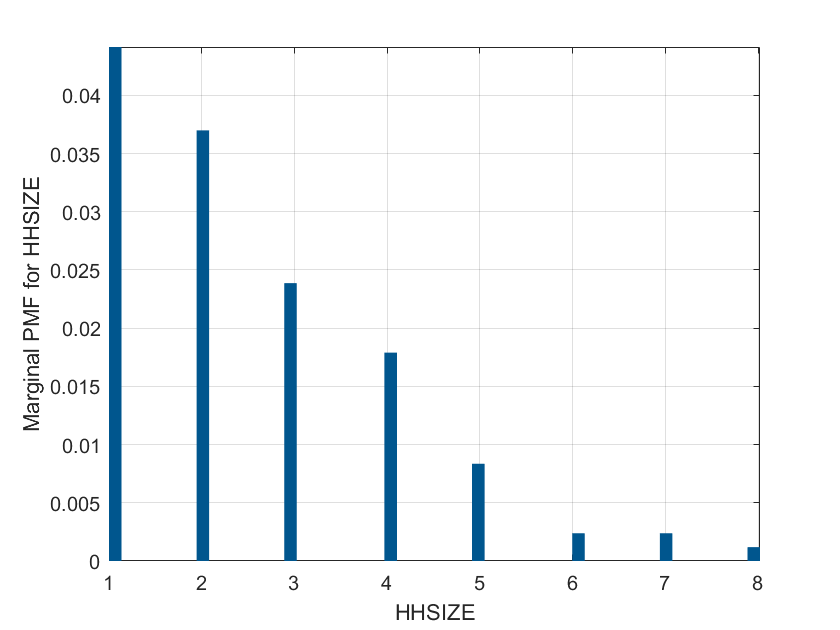

% See Function "PMF_Marginal_H"
% See Function "PMF_Marginal_T"

histogram2(HHSIZE,TOTAL,52,'Normalization','probability')
xlabel('HHSIZE')
ylabel('TOTAL')
zlabel('Marginal PMF for HHSIZE')
view([0 0])

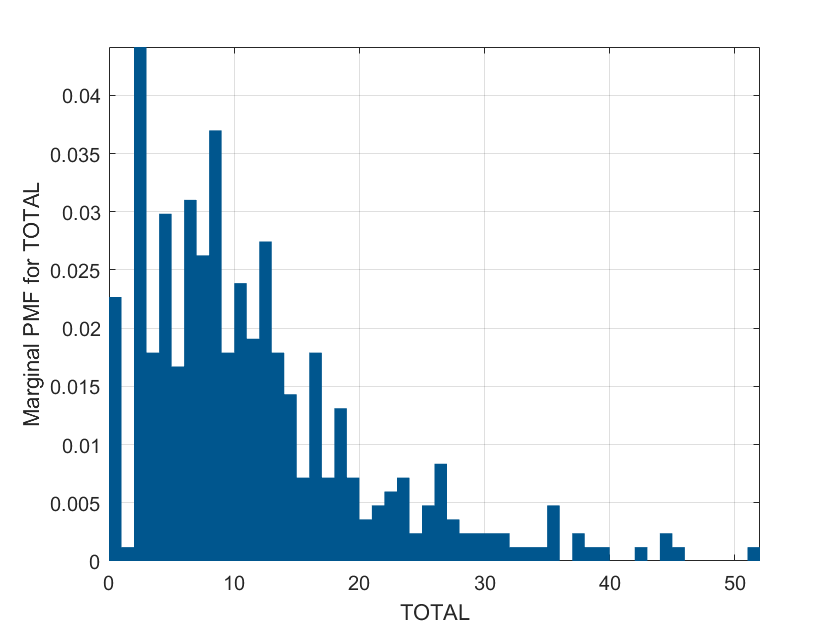


histogram2(TOTAL,HHSIZE,52,'Normalization','probability')
xlabel('TOTAL')
ylabel('HHSIZE')
zlabel('Marginal PMF for TOTAL')
view([0 0])

**Q2d**

Compute: 

(i) P(TOTAL = 4 | HHSIZE = 3); 

PMF_T4_H3 =PMF(3,4,TOTAL,HHSIZE)

PMF_T4_H3 = 0.0095

PMF_H3 = PMF_Marginal_H(3,TOTAL,HHSIZE)

PMF_Marginal_HHSIZE = 0

PMF_H3 = 0.1969

P_T4_WhenH3 =  PMF_T4_H3/PMF_H3

P_T4_WhenH3 = 0.0485

(ii) P(HHSIZE = 3 | TOTAL = 4); 

PMF_T4_H3 =PMF(3,4,TOTAL,HHSIZE)

PMF_T4_H3 = 0.0095

PMF_T4 = PMF_Marginal_T(4,TOTAL,HHSIZE)

PMF_Marginal_TOTAL = 0

PMF_T4 = 0.0740

P_H3_WhenT4 =  PMF_T4_H3/PMF_T4

P_H3_WhenT4 = 0.1290

(iii) P(HHSIZE =  3 | 2 <=TOTAL <= 4)

PMF_H3_TFrom2To4 =PMF(3,2,TOTAL,HHSIZE)+PMF(3,3,TOTAL,HHSIZE)+PMF(3,3,TOTAL,HHSIZE)

PMF_H3_TFrom2To4 = 0.0060

PMF_TFrom2To4 = PMF_Marginal_T(2,TOTAL,HHSIZE)+PMF_Marginal_T(3,TOTAL,HHSIZE)+PMF_Marginal_T(4,TOTAL,HHSIZE)

PMF_Marginal_TOTAL = 0

PMF_Marginal_TOTAL = 0

PMF_Marginal_TOTAL = 0

PMF_TFrom2To4 = 0.1778

PMF_H3_When_TFrom2To4 = PMF_H3_TFrom2To4/PMF_TFrom2To4

PMF_H3_When_TFrom2To4 = 0.0336

**Q2e**

Use your answers from parts a) and c) to determine whether TOTAL and HHSIZE are  independent random variables

PMF_H3_T4 =PMF(3,4,TOTAL,HHSIZE)

PMF_H3_T4 = 0.0095

PMF_T4 = PMF_Marginal_T(4,TOTAL,HHSIZE)

PMF_Marginal_TOTAL = 0

PMF_T4 = 0.0740

PMF_H3 = PMF_Marginal_H(3,TOTAL,HHSIZE)

PMF_Marginal_HHSIZE = 0

PMF_H3 = 0.1969

A = PMF_T4*PMF_H3

A = 0.0146

% since PMF_T4*PMF_H3 ≠ PMF_H3_T4, TOTAL and HHSIZE are not independent random variables